# Spiral Test

This is a test script for the spiral.m script. In this script the function is validated and examples of how to use this code is shown.

clear all; close all
addpath("Spiral pulley")

## Creating the basic spiral with dimensions

Here the basic spiral is defined that will be used to create all the other shapes

r1 = 1.2;
r2 = 3;
F0 = 13;
k = 2.5;
basic_spiral = spiral(r1,r2,F0,k); %Creating the constant force spiral object
theta_max = 1.5*pi;

## Constant force spiral

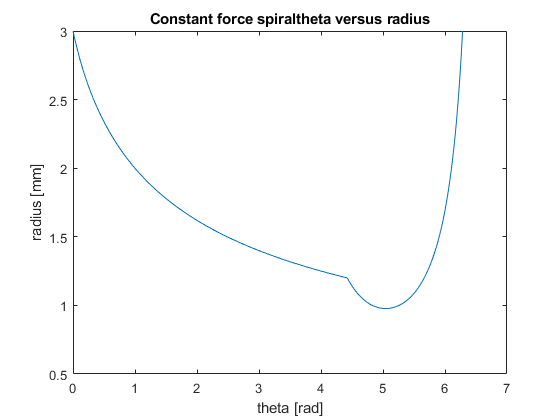

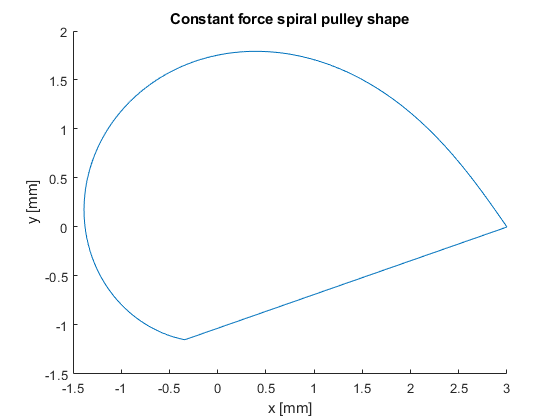

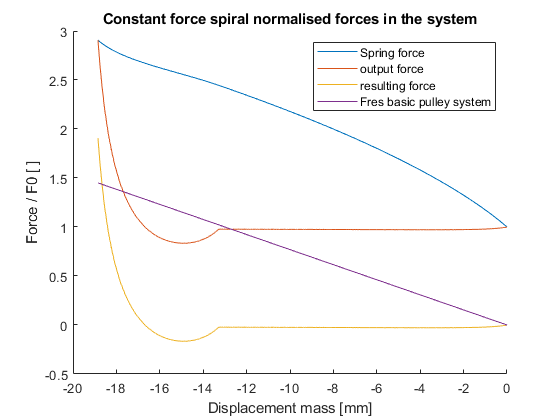

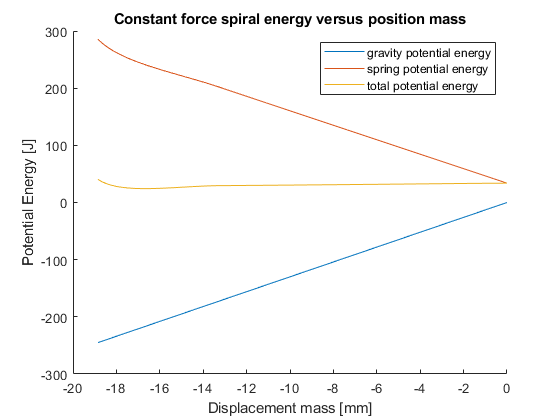

cf_basic_spiral = basic_spiral.Spiral_constant_Force(1000); %computing the shape of the constant force spiral
cf_basic_spiral.plot_shape() %unclosed shape
cf_basic_spiral = cf_basic_spiral.close_shape(200); %closing the shape
cf_basic_spiral = cf_basic_spiral.plot_all(1000,0);

## Archimides spiral

archimedes_spiral = basic_spiral.archimedes(1000, theta_max);
archimedes_spiral = archimedes_spiral.close_shape(100)

archimedes_spiral =   spiral with properties:

                   r1: 1.2000
                   r2: 3
                   F0: 13
                    k: 2.5000
                 name: 'Archimedes spiral'
                    S: []
                    r: [1×1102 double]
                theta: [1×1102 double]
                    x: [1×1102 double]
                    y: [1×1102 double]
    spiral_max_stroke: []
          curve_angle: []
                 x_m2: []
                  x_m: []
                  x_s: []
                   rs: []
                  phi: []
        spring_offset: []
                   Fm: []
                   Fs: []
                 Fres: []
           Fm_control: []
                   Eg: []
                   Es: []
                 Etot: []


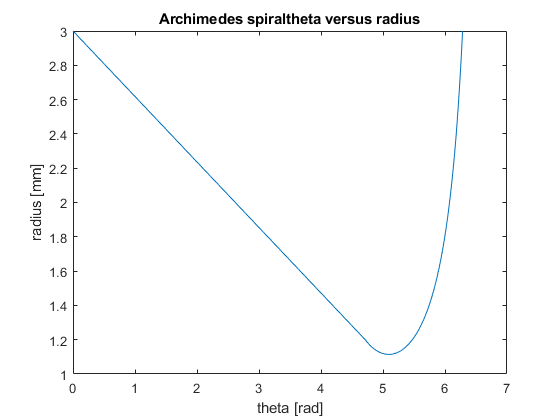

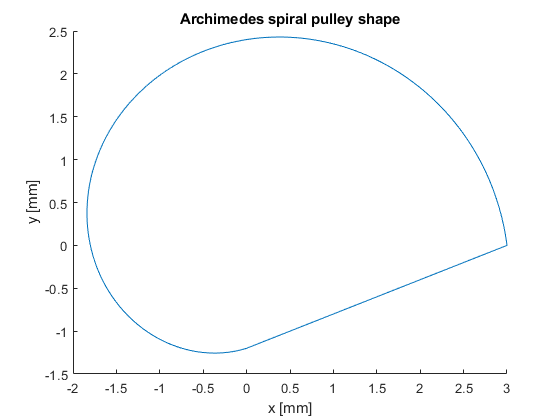

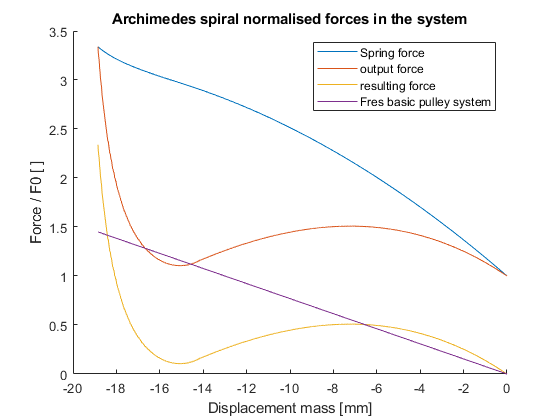

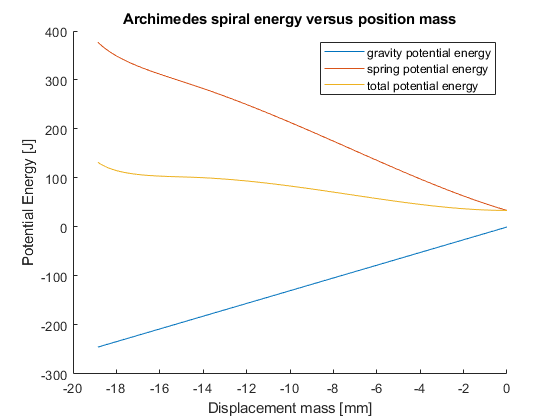

archimedes_spiral = archimedes_spiral.plot_all(1000,0);

## Logarithmic spiral

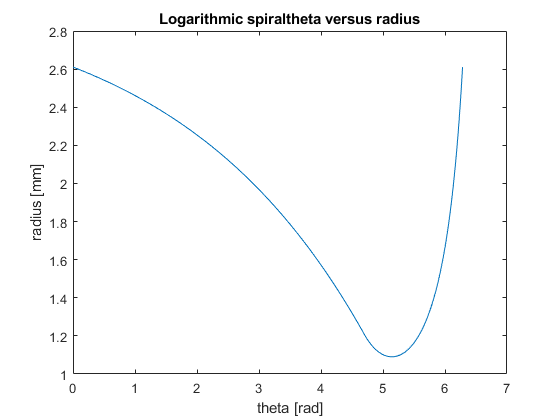

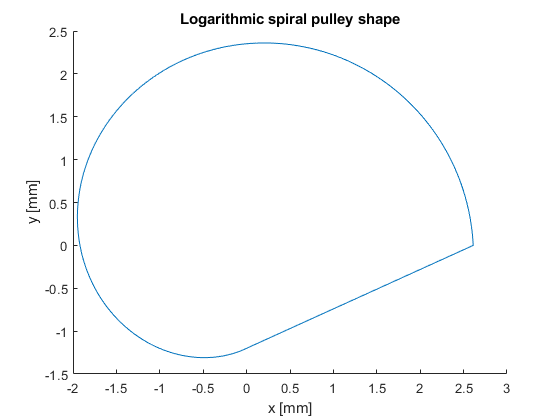

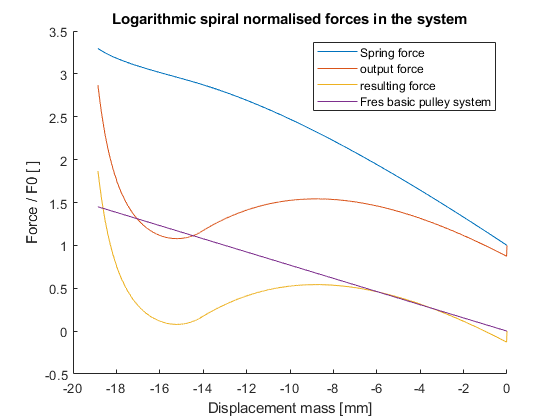

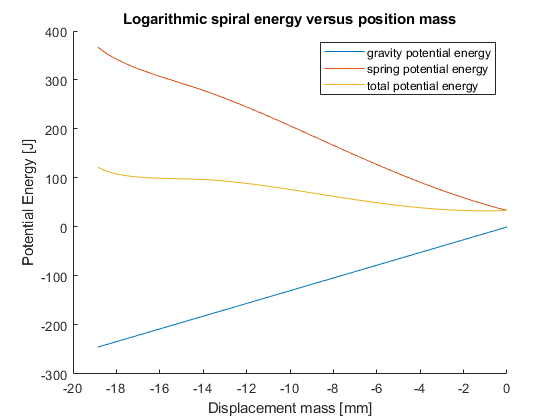

logarithmic_spiral = basic_spiral.logarithmic(1000, theta_max, pi/2*0.8);
logarithmic_spiral = logarithmic_spiral.close_shape(200);
logarithmic_spiral = logarithmic_spiral.plot_all(1000,0);